## ** Section 0 — Setup: Load Parameters**

%% Section 0 — Setup: Load Parameters
% This must be run first. Every other section depends on |params|.

clc;
params = delta_params();

=== Delta Robot Parameters Loaded ===
  Rb (base circumradius)     : 0.2000 m
  Rp (platform circumradius) : 0.0600 m
  L1 (upper arm)             : 0.2000 m
  L2 (forearm)               : 0.4000 m
  Joint limits               : [-20.0, 90.0] deg
  Max reach (approx.)        : 0.6000 m



% Quick sanity check on values
assert(params.Rb > 0,  'Rb must be positive');
assert(params.Rp > 0,  'Rp must be positive');
assert(params.L1 > 0,  'L1 must be positive');
assert(params.L2 > 0,  'L2 must be positive');
assert(params.L2 > params.L1, 'L2 should be longer than L1 for a typical delta robot');

disp('✓  Parameters loaded and validated successfully.')

✓  Parameters loaded and validated successfully.


## Section 1 — Test IK at the Workspace Centre

- The centre of the workspace (x=0, y=0) is symmetric.

- All three chains should return the same joint angle

p_centre = [0; 0; 0.35];   % [m] — centre of workspace, 350 mm below base

[theta_centre, valid_centre] = delta_IK(params, p_centre);
theta_centre_deg = rad2deg(theta_centre);

fprintf('Target point:  [%.4f,  %.4f,  %.4f] m\n', p_centre);

Target point:  [0.0000,  0.0000,  0.3500] m


fprintf('IK valid:       %d\n', valid_centre);

IK valid:       1


fprintf('Joint angles:  [%.4f,  %.4f,  %.4f] deg\n', theta_centre_deg);

Joint angles:  [30.2294,  30.2294,  30.2294] deg



% Because the point is on the symmetry axis all three angles must be equal
angle_spread = max(theta_centre_deg) - min(theta_centre_deg);
fprintf('Angle spread:   %.2e deg  (should be ~0 for centre point)\n', angle_spread);

Angle spread:   0.00e+00 deg  (should be ~0 for centre point)



assert(valid_centre == 1,    'IK failed for centre point — check workspace limits in delta_params');
assert(angle_spread < 1e-8,  'Angles should be equal at centre — check phi values in delta_params');

disp('✓  IK at centre passed.')

✓  IK at centre passed.


## Section 2 — Test IK at an Off-Centre Point

- Moving off-centre breaks the symmetry — all three angles should now differ.

p_offset = [0.05; 0.03; 0.32];   % [m]

[theta_offset, valid_offset] = delta_IK(params, p_offset);
theta_offset_deg = rad2deg(theta_offset);

fprintf('Target point:  [%.4f,  %.4f,  %.4f] m\n', p_offset);

Target point:  [0.0500,  0.0300,  0.3200] m


fprintf('IK valid:       %d\n', valid_offset);

IK valid:       1


fprintf('Joint angles:  [%.4f,  %.4f,  %.4f] deg\n', theta_offset_deg);

Joint angles:  [12.0003,  25.5865,  38.4139] deg



assert(valid_offset == 1, 'IK failed for off-centre point');

spread2 = max(theta_offset_deg) - min(theta_offset_deg);
assert(spread2 > 0.1, 'Angles should differ for off-centre point');

disp('✓  IK at off-centre point passed.')

✓  IK at off-centre point passed.


## Section 3 — Test IK Rejects an Unreachable Point

- A point far outside the workspace must return valid = 0.

- This confirms the error-handling in delta_IK works correctly.

p_unreachable = [0.60; 0.00; 0.50];   % [m] — far outside reach

[~, valid_unreachable, msg_unreachable] = delta_IK(params, p_unreachable);

fprintf('Target:        [%.2f,  %.2f,  %.2f] m  (deliberately unreachable)\n', p_unreachable);

Target:        [0.60,  0.00,  0.50] m  (deliberately unreachable)


fprintf('IK valid:       %d  (expected 0)\n', valid_unreachable);

IK valid:       0  (expected 0)


fprintf('Reason:         %s\n', msg_unreachable);

Reason:         Point outside Cartesian workspace bounding box.



assert(valid_unreachable == 0, 'IK should return valid=0 for an unreachable point');

disp('✓  Unreachable-point rejection passed.')

✓  Unreachable-point rejection passed.


## Section 4 — FK Consistency Test 

- Run IK to get joint angles, then run FK on those angles.

- The FK output must match the original target to within floating-point precision.

- This is the e_cons metric required by the project specification.

test_points = [
     0.00,  0.00,  0.35;   % centre
     0.05,  0.00,  0.30;   % offset in x
     0.00,  0.05,  0.32;   % offset in y
    -0.04,  0.03,  0.38;   % offset in x and y
     0.02, -0.02,  0.28;   % close to base
]';   % each column is one point  [3 x N]

N = size(test_points, 2);
e_cons_all = zeros(1, N);

fprintf('%-5s  %-32s  %-14s  %-8s\n', 'Pt', 'Target (x, y, z) [m]', 'e_cons [m]', 'Pass?');

Pt     Target (x, y, z) [m]              e_cons [m]      Pass?   


fprintf('%s\n', repmat('-', 1, 65));

-----------------------------------------------------------------



all_passed = true;
for k = 1:N
    p_k = test_points(:, k);
    [th_k,  ok_ik] = delta_IK(params, p_k);
    [p_fk,  ok_fk] = delta_FK(params, th_k);
    e_cons_all(k)  = norm(p_fk - p_k);
    passed         = ok_ik && ok_fk && (e_cons_all(k) < 1e-10);
    all_passed     = all_passed && passed;
    fprintf('%-5d  [%7.4f, %7.4f, %7.4f]       %.3e       %s\n', ...
        k, p_k(1), p_k(2), p_k(3), e_cons_all(k), ...
        string(passed).upper.replace("TRUE","PASS").replace("FALSE","FAIL"));
end

1      [ 0.0000,  0.0000,  0.3500]       1.479e-17       PASS
2      [ 0.0500,  0.0000,  0.3000]       5.724e-17       PASS
3      [ 0.0000,  0.0500,  0.3200]       3.217e-17       PASS
4      [-0.0400,  0.0300,  0.3800]       7.244e-17       PASS
5      [ 0.0200, -0.0200,  0.2800]       5.123e-17       PASS



fprintf('%s\n', repmat('-', 1, 65));

-----------------------------------------------------------------


fprintf('Mean e_cons: %.3e m\n', mean(e_cons_all));

Mean e_cons: 4.557e-17 m


fprintf('Max  e_cons: %.3e m\n', max(e_cons_all));

Max  e_cons: 7.244e-17 m



assert(all_passed, 'FK consistency check failed — see table above');
disp('✓  FK consistency test passed for all 5 points.')

✓  FK consistency test passed for all 5 points.


## Section 5 — Visualise FK Consistency Error

- Bar chart of the consistency error across all test points.

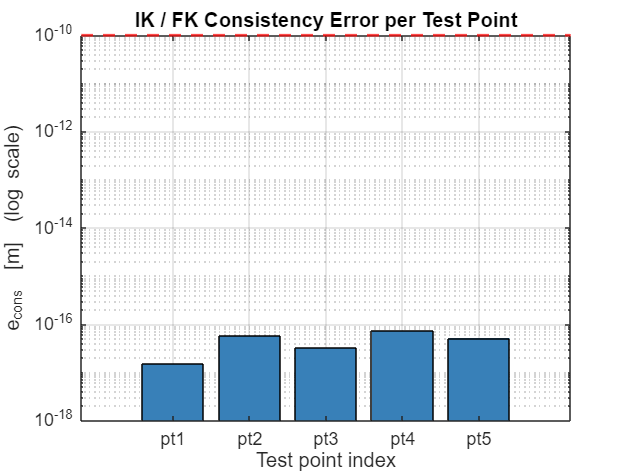

figure('Name', 'FK Consistency Error', 'Color', 'w');
bar(e_cons_all, 'FaceColor', [0.22 0.50 0.72]);
yline(1e-10, 'r--', 'LineWidth', 1.5, 'Label', 'Pass threshold 1e-10');
set(gca, 'YScale', 'log');
xlabel('Test point index');
ylabel('e_{cons}  [m]  (log scale)');
title('IK / FK Consistency Error per Test Point');
xticks(1:N);
xticklabels(arrayfun(@(k) sprintf('pt%d',k), 1:N, 'UniformOutput', false));
grid on;


disp('✓  Consistency error plot generated.')

✓  Consistency error plot generated.


## Section 6 — FK from Raw Joint Angles

- Test FK on its own: give it angles directly (not from IK) and check the output.

theta_manual = deg2rad([40; 45; 42]);   % [rad] — arbitrary angles

[p_manual, valid_manual] = delta_FK(params, theta_manual);

fprintf('Input angles:  [%.2f,  %.2f,  %.2f] deg\n', rad2deg(theta_manual));

Input angles:  [40.00,  45.00,  42.00] deg


fprintf('FK valid:       %d\n', valid_manual);

FK valid:       1


fprintf('EE position:   [%.6f,  %.6f,  %.6f] m\n', p_manual);

EE position:   [0.011266,  -0.008467,  0.412171] m



% Verify by running IK on the FK result — should recover the original angles
[theta_back, ok_back] = delta_IK(params, p_manual);
e_roundtrip = norm(theta_back - theta_manual);
fprintf('IK round-trip angle error: %.3e rad  (should be < 1e-10)\n', e_roundtrip);

IK round-trip angle error: 2.719e-16 rad  (should be < 1e-10)



assert(valid_manual == 1, 'FK failed for manual angles');
assert(e_roundtrip < 1e-10, 'FK -> IK round-trip failed');

disp('✓  Direct FK test passed.')

✓  Direct FK test passed.


## Section 7 — Workspace Scan and 3-D Plot

- It generates the reachable workspace point cloud and a 3-D figure.

- lower 'res' to 15 for a fast preview, raise to 40 for a detailed scan.

[delta_workspace] Scanning 15625 grid points (res=25)...
[delta_workspace] Done: 6795 / 15625 points reachable (43.5%) in 0.17 s.
[delta_workspace] Workspace bounds (reachable points):
  X: [-0.2000, 0.2000] m
  Y: [-0.2000, 0.2000] m
  Z: [0.1750, 0.5500] m
  Approximate volume: 35390.6 cm^3


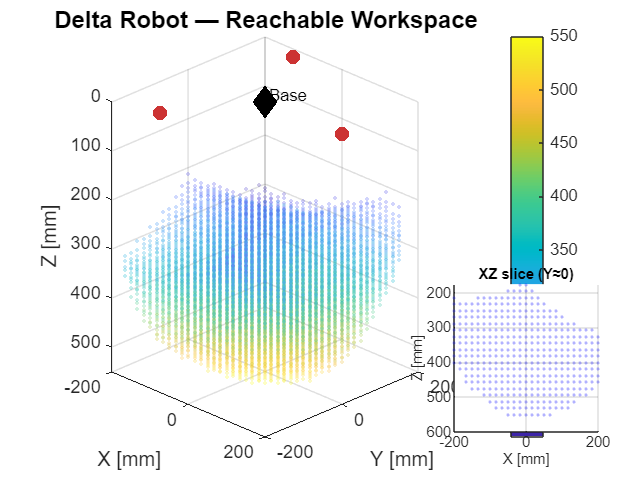

[delta_workspace] Plot generated.


[ws_points, ws_in] = delta_workspace(params, 'res', 25);


reach = ws_points(ws_in, :);   % extract only reachable points
fprintf('\nReachable: %d / %d sampled points (%.1f%%)\n', ...
    sum(ws_in), size(ws_points,1), 100*mean(ws_in));


Reachable: 6795 / 15625 sampled points (43.5%)


fprintf('X range: [%.4f, %.4f] m\n', min(reach(:,1)), max(reach(:,1)));

X range: [-0.2000, 0.2000] m


fprintf('Y range: [%.4f, %.4f] m\n', min(reach(:,2)), max(reach(:,2)));

Y range: [-0.2000, 0.2000] m


fprintf('Z range: [%.4f, %.4f] m\n', min(reach(:,3)), max(reach(:,3)));

Z range: [0.1750, 0.5500] m



% Update ws_lim hint (copy these values into delta_params.m + small margin)
fprintf('\nSuggested ws_lim for delta_params.m:\n');


Suggested ws_lim for delta_params.m:


margin = 0.01;
fprintf('  params.ws_lim = [ %.3f,  %.3f;\n', min(reach(:,1))-margin, max(reach(:,1))+margin);

  params.ws_lim = [ -0.210,  0.210;


fprintf('                    %.3f,  %.3f;\n', min(reach(:,2))-margin, max(reach(:,2))+margin);

                    -0.210,  0.210;


fprintf('                    %.3f,  %.3f ];\n', min(reach(:,3))-margin, max(reach(:,3))+margin);

                    0.165,  0.560 ];



disp('✓  Workspace scan complete.')

✓  Workspace scan complete.


## Section 8 — Workspace Membership Tests

- Single-point checks: should be fast (no full scan)

test_pts_ws = {
    [0.00;  0.00;  0.35], 'centre (should be IN)';
    [0.10;  0.00;  0.30], 'slight offset (should be IN)';
    [0.60;  0.00;  0.50], 'far outside (should be OUT)';
    [0.00;  0.00;  0.01], 'too close to base (should be OUT)';
};

fprintf('\n%-40s  %-8s\n', 'Point description', 'Result');


Point description                         Result  


fprintf('%s\n', repmat('-', 1, 52));

----------------------------------------------------


for k = 1:size(test_pts_ws, 1)
    pt  = test_pts_ws{k,1};
    lbl = test_pts_ws{k,2};
    in  = delta_workspace(params, 'check', pt);
    fprintf('%-40s  %s\n', lbl, string(logical(in)).upper.replace("TRUE","IN ").replace("FALSE","OUT"));
end

centre (should be IN)                     OUT
OUT                                       IN 
slight offset (should be IN)              IN 
OUT                                       IN 
far outside (should be OUT)               IN 
OUT                                       IN 
too close to base (should be OUT)         OUT
OUT                                       IN 



disp('✓  Workspace membership tests complete.')

✓  Workspace membership tests complete.


## Section 9 — Singularity Check at Key Configurations

- Check condition number and singularity flags at three configurations:

- workspace centre — should be near-isotropic (cond ≈ 1)

- slightly off-centre

- arms nearly fully extended (near Type-2 singularity)

configs = {
    delta_IK(params, [0.00; 0.00; 0.35]), 'Centre (z=350mm)';
    delta_IK(params, [0.08; 0.00; 0.30]), 'Off-centre (x=80mm)';
    deg2rad([80; 80; 80]),                 'Arms near fully extended (80 deg)';
};

fprintf('\n%-30s  %-8s  %-8s  %-10s  %-8s\n', ...
    'Configuration', 'Type-1', 'Type-2', 'cond(Jx)', 'Safe?');


Configuration                   Type-1    Type-2    cond(Jx)    Safe?   


fprintf('%s\n', repmat('-', 1, 72));

------------------------------------------------------------------------



for k = 1:size(configs,1)
    th_k  = configs{k,1};
    lbl   = configs{k,2};
    [~, ~, t1, t2, info] = delta_singularity(params, th_k);
    safe  = ~t1 && ~t2 && info.cond_Jx < 50;
    fprintf('%-30s  %-8d  %-8d  %-10.2f  %s\n', ...
        lbl, t1, t2, info.cond_Jx, string(safe).upper.replace("TRUE","YES").replace("FALSE","WARN"));
end

=== Singularity Analysis ===
  Joint angles:  [30.23, 30.23, 30.23] deg
  EE position:   [0.0000, -0.0000, 0.3500] m

  --- Cartesian Jacobian Jx ---
    0.7820    0.0000   -0.6233
   -0.3910    0.6772   -0.6233
   -0.3910   -0.6772   -0.6233

  det(Jx)        = -0.990260
  cond(Jx)       = 1.13
  Type-1 singularity (det(Jx)≈0): false

  --- Joint Jacobian diag(Jq) ---
  [-0.1864,  -0.1864,  -0.1864]
  Type-2 singularity (any Jq_ii≈0): false

  Angles between forearms:
  n1^n2=85.3°,  n2^n3=85.3°,  n3^n1=85.3°


Centre (z=350mm)                0         0         1.13        YES


=== Singularity Analysis ===
  Joint angles:  [-1.15, 33.91, 33.91] deg
  EE position:   [0.0800, 0.0000, 0.3000] m

  --- Cartesian Jacobian Jx ---
    0.6499   -0.0000   -0.7600
   -0.5825    0.6625   -0.4710
   -0.5825   -0.6625   -0.4710

  det(Jx)        = -0.992120
  cond(Jx)       = 1.13
  Type-1 singularity (det(Jx)≈0): false

  --- Joint Jacobian diag(Jq) ---
  [-0.1494,  -0.1747,  -0.1747]
  Type-2 singularity (any Jq_ii≈0): false

  Angles between forearms:
  n1^n2=91.2°,  n2^n3=83.0°,  n3^n1=91.2°


Off-centre (x=80mm)             0         0         1.13        YES


=== Singularity Analysis ===
  Joint angles:  [80.00, 80.00, 80.00] deg
  EE position:   [-0.0000, 0.0000, 0.5568] m

  --- Cartesian Jacobian Jx ---
    0.4368         0   -0.8995
   -0.2184    0.3783   -0.8995
   -0.2184   -0.3783   -0.8995

  det(Jx)        = -0.445953
  cond(Jx)       = 2.91
  Type-1 singularity (det(Jx)≈0): false

  --- Joint Jacobian diag(Jq) ---
  [-0.1173,  -0.1173,  -0.1173]
  Type-2 singularity (any Jq_ii≈0): false

  Angles between forearms:
  n1^n2=44.5°,  n2^n3=44.5°,  n3^n1=44.5°


Arms near fully extended (80 deg)  0         0         2.91        YES



disp('✓  Singularity checks complete.')

✓  Singularity checks complete.


## Section 10 — Condition Number Along a Circle Trajectory

- Simulate a circular trajectory and plot cond(Jx) at every point.

- Any spike above 50 would mean the trajectory passes near a singularity.

N_traj = 72;
r_circ  = 0.06;    % [m]  circle radius
z_circ  = 0.35;    % [m]  circle depth

angles_traj = linspace(0, 2*pi, N_traj+1);
angles_traj(end) = [];

cond_traj   = nan(1, N_traj);
valid_traj  = false(1, N_traj);

for k = 1:N_traj
    p_k = [r_circ*cos(angles_traj(k));
           r_circ*sin(angles_traj(k));
           z_circ];
    [th_k, ok_k] = delta_IK(params, p_k);
    if ok_k
        [~,~,~,~, inf_k] = delta_singularity(params, th_k);
        cond_traj(k)  = inf_k.cond_Jx;
        valid_traj(k) = true;
    end
end

=== Singularity Analysis ===
  Joint angles:  [16.43, 38.56, 38.56] deg
  EE position:   [0.0600, -0.0000, 0.3500] m

  --- Cartesian Jacobian Jx ---
    0.6796    0.0000   -0.7336
   -0.5205    0.6417   -0.5633
   -0.5205   -0.6417   -0.5633

  det(Jx)        = -0.981339
  cond(Jx)       = 1.21
  Type-1 singularity (det(Jx)≈0): false

  --- Joint Jacobian diag(Jq) ---
  [-0.1792,  -0.1898,  -0.1898]
  Type-2 singularity (any Jq_ii≈0): false

  Angles between forearms:
  n1^n2=86.6°,  n2^n3=79.8°,  n3^n1=86.6°
=== Singularity Analysis ===
  Joint angles:  [16.49, 37.52, 39.54] deg
  EE position:   [0.0598, 0.0052, 0.3500] m

  --- Cartesian Jacobian Jx ---
    0.6800   -0.0131   -0.7331
   -0.5227    0.6335   -0.5705
   -0.5172   -0.6501   -0.5567

  det(Jx)        = -0.981353
  cond(Jx)       = 1.21
  Type-1 singularity (det(Jx)≈0): false

  --- Joint Jacobian diag(Jq) ---
  [-0.1792,  -0.1892,  -0.1905]
  Type-2 singularity (any Jq_ii≈0): false

  Angles 


fprintf('Trajectory: %d / %d points valid\n', sum(valid_traj), N_traj);

Trajectory: 72 / 72 points valid


fprintf('Max cond(Jx) on trajectory: %.2f\n', max(cond_traj(valid_traj)));

Max cond(Jx) on trajectory: 1.21


if max(cond_traj(valid_traj)) < 50
    disp('✓  Trajectory is safe — no singularity risk.')
else
    warning('Trajectory passes near a singularity — consider adjusting radius or depth.');
end

✓  Trajectory is safe — no singularity risk.


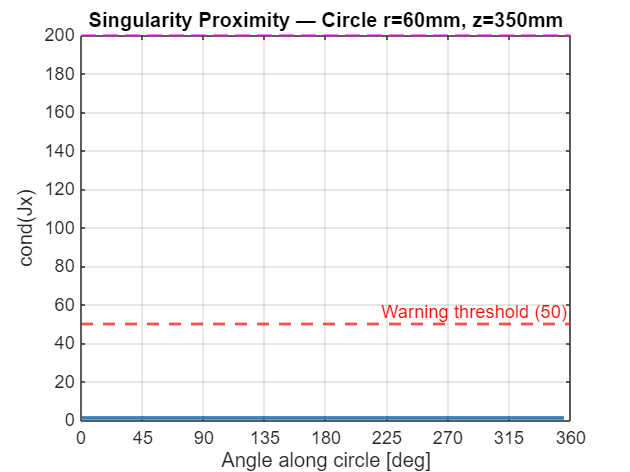


figure('Name', 'Condition Number Along Circle Trajectory', 'Color', 'w');
plot(rad2deg(angles_traj(valid_traj)), cond_traj(valid_traj), ...
    'LineWidth', 2, 'Color', [0.22 0.50 0.72]);
yline(50,  'r--', 'LineWidth', 1.5, 'Label', 'Warning threshold (50)');
yline(200, 'm--', 'LineWidth', 1,   'Label', 'Danger threshold (200)');
xlabel('Angle along circle [deg]');
ylabel('cond(Jx)');
title(sprintf('Singularity Proximity — Circle r=%.0fmm, z=%.0fmm', ...
    r_circ*1e3, z_circ*1e3));
grid on; xlim([0 360]); xticks(0:45:360);

## Section 11 — Joint Angle Profile Along the Same Trajectory

- Plot how the three joint angles change as the robot traces the circle.

- This is what the motor commands would look like in Mode 2 (IK mode).

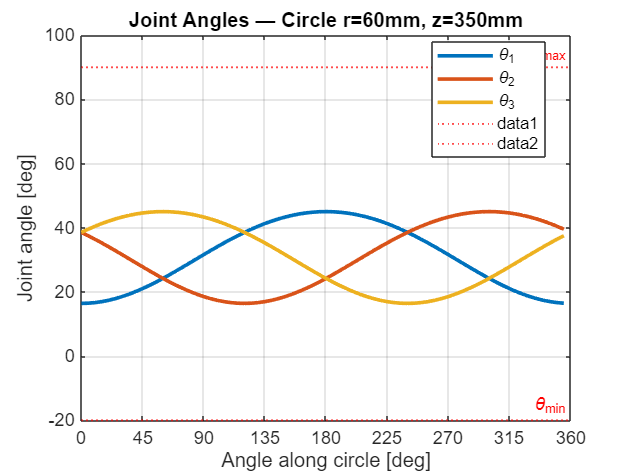

theta_traj = nan(3, N_traj);
for k = 1:N_traj
    p_k = [r_circ*cos(angles_traj(k));
           r_circ*sin(angles_traj(k));
           z_circ];
    [th_k, ok_k] = delta_IK(params, p_k);
    if ok_k
        theta_traj(:,k) = rad2deg(th_k);
    end
end

figure('Name', 'Joint Angles Along Circle Trajectory', 'Color', 'w');
plot(rad2deg(angles_traj), theta_traj', 'LineWidth', 2);
legend('\theta_1', '\theta_2', '\theta_3', 'Location', 'best');
xlabel('Angle along circle [deg]');
ylabel('Joint angle [deg]');
title(sprintf('Joint Angles — Circle r=%.0fmm, z=%.0fmm', r_circ*1e3, z_circ*1e3));
yline(rad2deg(params.th_min), 'r:', 'LineWidth', 1, 'Label', '\theta_{min}');
yline(rad2deg(params.th_max), 'r:', 'LineWidth', 1, 'Label', '\theta_{max}');
grid on; xlim([0 360]); xticks(0:45:360);


disp('✓  Trajectory plots generated.')

✓  Trajectory plots generated.


## Section 12 — Final Summary

- Summarise the pass/fail status of every test in one place.

fprintf('\n');
fprintf('========================================\n');

fprintf('   DELTA ROBOT TEST SUITE — SUMMARY\n');

   DELTA ROBOT TEST SUITE — SUMMARY


fprintf('========================================\n');

tests = {
    'Parameters loaded',          true;
    'IK at centre',               valid_centre;
    'IK at off-centre point',     valid_offset;
    'Unreachable point rejected',  ~valid_unreachable;
    'FK consistency (all 5 pts)', all_passed;
    'Direct FK + round-trip',     valid_manual && e_roundtrip < 1e-10;
    'Workspace scan',             sum(ws_in) > 100;
    'Trajectory safe (cond<50)',  max(cond_traj(valid_traj)) < 50;
};
all_ok = true;
for k = 1:size(tests,1)
    status = tests{k,2};
    all_ok = all_ok && status;
    icon   = string(status).upper.replace("TRUE","PASS").replace("FALSE","FAIL");
    fprintf('  [%s]  %s\n', icon, tests{k,1});
end

  [PASS]  Parameters loaded
  [PASS]  IK at centre
  [PASS]  IK at off-centre point
  [PASS]  Unreachable point rejected
  [PASS]  FK consistency (all 5 pts)
  [PASS]  Direct FK + round-trip
  [PASS]  Workspace scan
  [PASS]  Trajectory safe (cond<50)


fprintf('========================================\n');

if all_ok
    disp('  ALL TESTS PASSED — model is ready.')
else
    disp('  SOME TESTS FAILED — review output above.')
end

  ALL TESTS PASSED — model is ready.


fprintf('========================================\n');